# $k_{\mathrm{max}}^{\mathrm{vivo}}$ and *in vitro* $k_{\mathrm{cat}}$

clear

$k_{\mathrm{max}}^{\mathrm{vivo}}$=$\frac{v\left(C\right)}{E\left(C\right)}$

abundance_data

kcat_data_plant


abundance_per_EC_mg_gDW_combined_all = [abundance_per_EC_mg_gDW_Pyl abundance_per_EC_mg_gDW_Piques abundance_per_EC_mg_gDW_Seaton];

## Flux estimation $v\left(C\right)$

## (1) pFBA and measured growth rate

flux_estimation_pFBA

 > The solver compatibility is not tested with MATLAB R2019a.
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


Diff_flux_pFBA = Diff_flux;

v_umol_gDW_sec(v_umol_gDW_sec==0) = nan;

kapp_pFBA = v_umol_gDW_sec./abundance_per_EC_mg_gDW_combined_all;

kmax_vivo_pFBA = max(kapp_pFBA,[],2,'omitnan');
clear v_umol_gDW_sec Diff_flux

#### Correlation $k_{\mathrm{max}}^{\mathrm{vivo}}$ and *in vitro *$k_{\mathrm{cat}}$ - all enzymes

disp('Number of enzymes:')

Number of enzymes:


length(intersect(find(~isnan(kcat_BRENDA_max)),find(~isnan(kmax_vivo_pFBA))))

ans = 70


disp('Number of enzymes with etha > 1:')

Number of enzymes with etha > 1:


sum(kcat_BRENDA_max<kmax_vivo_pFBA)

ans = 22


disp('Correlation kmax_vivo to mean kcat:')

Correlation kmax_vivo to mean kcat:


C=corr(log(kcat_BRENDA_mean),log(kmax_vivo_pFBA),'rows','pairwise')

C = 0.1630

Csp=corr(log(kcat_BRENDA_mean),log(kmax_vivo_pFBA),'type','Spearman','rows','pairwise')

Csp = 0.2579


disp('Correlation kmax_vivo to max kcat:')

Correlation kmax_vivo to max kcat:


C=corr(log(kcat_BRENDA_max),log(kmax_vivo_pFBA),'rows','pairwise')

C = 0.1759

Csp=corr(log(kcat_BRENDA_mean),log(kmax_vivo_pFBA),'type','Spearman','rows','pairwise')

Csp = 0.2579

#### Correlation $k_{\mathrm{max}}^{\mathrm{vivo}}$ and *in vitro* $k_{\mathrm{cat}}$ - enzymes with Vmax, kcat and v estimate

disp('Number of enzymes:')

Number of enzymes:


load('Result1.mat',"kapp_Vmax_combined_all_max")
kmax_vivo_pFBA_temp=kmax_vivo_pFBA;
kmax_vivo_pFBA_temp(isnan(kapp_Vmax_combined_all_max)) = nan;
kmax_vivo_pFBA_temp(isnan(kcat_BRENDA_max)) = nan;

length(intersect(find(~isnan(kcat_BRENDA_max)),find(~isnan(kmax_vivo_pFBA_temp))))

ans = 20


disp('Correlation kmax_vivo to mean kcat:')

Correlation kmax_vivo to mean kcat:


C=corr(log(kcat_BRENDA_mean),log(kmax_vivo_pFBA_temp),'rows','pairwise')

C = 0.0245

Csp=corr(log(kcat_BRENDA_mean),log(kmax_vivo_pFBA_temp),'type','Spearman','rows','pairwise')

Csp = 0.1158


disp('Correlation kmax_vivo to max kcat:')

Correlation kmax_vivo to max kcat:


C=corr(log(kcat_BRENDA_max),log(kmax_vivo_pFBA_temp),'rows','pairwise')

C = 0.0290

Csp=corr(log(kcat_BRENDA_max),log(kmax_vivo_pFBA_temp),'type','Spearman','rows','pairwise')

Csp = 0.1188

#### Correlation $k_{\mathrm{max}}^{\mathrm{vivo}}$ and $k_{\mathrm{cat}}^{\mathrm{Vmax}}$ - 22 enzymes with Vmax

disp('Number of enzymes:')

Number of enzymes:


length(intersect(find(~isnan(kapp_Vmax_combined_all_max)),find(~isnan(kmax_vivo_pFBA_temp))))

ans = 20


disp('Correlation kmax_vivo to kcat_Vmax:')

Correlation kmax_vivo to kcat_Vmax:


C=corr(log(kapp_Vmax_combined_all_max),log(kmax_vivo_pFBA_temp),'rows','pairwise')

C = -0.1024

Csp=corr(log(kapp_Vmax_combined_all_max),log(kmax_vivo_pFBA_temp),'type','Spearman','rows','pairwise')

Csp = -0.1835

## (2) pFBA and constraint c/o ratio, starch/sucrose ratio, and growth

flux_estimation_co_ratios
Diff_flux_ratios = Diff_flux;

[numRow,numCol]=size(v_umol_gDW_sec)

numRow = 11

numCol = 16

for i=1:numRow
    for j=1:numCol
        v_umol_gDW_sec{i,j}(v_umol_gDW_sec{i,j}==0)=nan;
    end
end

kapp_ratios = cellfun(@(x) x./abundance_per_EC_mg_gDW_combined_all,v_umol_gDW_sec,'un',0);
kmax_vivo_ratios = cellfun(@(x) max(x,[],2,'omitnan'),kapp_ratios,'UniformOutput',false);
clear v_umol_gDW_sec Diff_flux

#### Correlation $k_{\mathrm{max}}^{\mathrm{vivo}}$ and $k_{\mathrm{cat}}$ - all enzymes

disp('Number of enzymes:')

Number of enzymes:


cellfun(@(x) length(intersect(find(~isnan(kcat_BRENDA_max)),find(~isnan(x)))), kmax_vivo_ratios,'UniformOutput',false)

ans = 11×16 cell array
    {[71]}    {[73]}    {[71]}    {[71]}    {[74]}    {[70]}    {[73]}    {[72]}    {[72]}    {[71]}    {[72]}    {[75]}    {[72]}    {[72]}    {[71]}    {[71]}
    {[71]}    {[71]}    {[72]}    {[73]}    {[71]}    {[71]}    {[70]}    {[72]}    {[73]}    {[74]}    {[73]}    {[73]}    {[74]}    {[74]}    {[73]}    {[71]}
    {[72]}    {[70]}    {[72]}    {[72]}    {[71]}    {[70]}    {[73]}    {[70]}    {[71]}    {[73]}    {[73]}    {[73]}    {[70]}    {[70]}    {[75]}    {[76]}
    {[72]}    {[70]}    {[72]}    {[73]}    {[69]}    {[73]}    {[73]}    {[70]}    {[70]}    {[71]}    {[71]}    {[74]}    {[70]}    {[70]}    {[73]}    {[73]}
    {[70]}    {[71]}    {[72]}    {[71]}    {[71]}    {[70]}    {[71]}    {[70]}    {[72]}    {[70]}    {[70]}    {[70]}    {[71]}    {[71]}    {[70]}    {[74]}
    {[72]}    {[70]}    {[70]}    {[72]}    {[71]}    {[70]}    {[72]}    {[71]}    {[71]}    {[70]}    {[70]}    {[70]}    {[70]}    {[70]}    {[72]}    {[74]}
    {[70]} 


disp('Number of enzymes with etha > 1:')

Number of enzymes with etha > 1:


cellfun(@(x) sum(kcat_BRENDA_max<x), kmax_vivo_ratios)

ans =     15    19    18    16    18    18    21    20    17    15    16    19    18    18    14    14
    17    17    18    18    16    15    20    21    19    24    20    21    18    23    20    18
    24    19    17    17    14    19    20    19    21    21    20    21    20    20    20    21
    19    20    15    16    19    19    20    19    19    22    17    17    23    19    22    16
    18    17    16    17    13    20    19    19    16    20    18    21    15    15    20    21
    17    16    20    19    15    19    19    19    22    20    19    19    19    20    19    18
    17    16    22    21    18    20    25    19    15    18    20    18    23    21    17    19
    19    17    20    24    19    19    21    18    15    20    19    25    22    19    18    17
    18    18    21    21    15    21    15    19    19    15    18    19    18    18    21    20
    22    17    14    17    18    23    19    19    19    15    18    19    19    22    19    19



disp('Correlation kmax_vivo to mean kcat:')

Correlation kmax_vivo to mean kcat:


C=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_mean),log(x),'rows','pairwise'), kmax_vivo_ratios,'UniformOutput',false))

C =     0.3298    0.3418    0.3954    0.3876    0.3444    0.3539    0.3152    0.2466    0.3555    0.3881    0.3562    0.3327    0.4047    0.3561    0.2618    0.2617
    0.3967    0.3421    0.3993    0.3775    0.2755    0.3984    0.3995    0.3092    0.3572    0.2920    0.2915    0.3689    0.2748    0.3568    0.3326    0.3768
    0.3503    0.4049    0.3269    0.3375    0.3896    0.3468    0.3474    0.3451    0.3990    0.3230    0.3331    0.3228    0.3872    0.3903    0.2714    0.2915
    0.3943    0.3532    0.3766    0.3199    0.3363    0.3588    0.3386    0.3880    0.3994    0.3369    0.3658    0.3690    0.3142    0.3452    0.3586    0.3805
    0.4091    0.3812    0.3987    0.3825    0.3362    0.3957    0.3890    0.3479    0.3910    0.4052    0.3408    0.3438    0.2932    0.3872    0.3428    0.3228
    0.3638    0.3577    0.4016    0.3377    0.3733    0.3378    0.3435    0.3520    0.3283    0.4009    0.3948    0.4000    0.3477    0.3402    0.3601    0.3685
    0.4077    0.3082    0.3743

Csp=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_mean),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_ratios,'UniformOutput',false))

Csp =     0.3277    0.3264    0.4098    0.4031    0.3417    0.4017    0.3531    0.2762    0.3494    0.3992    0.3595    0.3224    0.4212    0.3649    0.2754    0.2716
    0.4022    0.4033    0.3982    0.4053    0.2997    0.4075    0.3893    0.3516    0.3534    0.3256    0.3120    0.3568    0.3463    0.3564    0.4109    0.3769
    0.3986    0.4168    0.3174    0.3109    0.4047    0.4030    0.3434    0.3975    0.4012    0.3696    0.3955    0.3754    0.3839    0.3852    0.3293    0.3574
    0.3993    0.4050    0.3807    0.2892    0.3614    0.3781    0.3630    0.3802    0.3833    0.2987    0.3544    0.3777    0.2897    0.3985    0.3651    0.3885
    0.3988    0.3738    0.3933    0.3955    0.3469    0.4013    0.3695    0.3969    0.3984    0.4079    0.3912    0.3914    0.3136    0.3825    0.3153    0.3204
    0.3446    0.4244    0.3954    0.3867    0.3819    0.3956    0.3673    0.4114    0.3785    0.4061    0.3928    0.3969    0.3951    0.3899    0.3466    0.3852
    0.4083    0.3225    0.37

max(C,[],"all")

ans = 0.4091

max(Csp,[],"all")

ans = 0.4244


disp('Correlation kmax_vivo to max kcat:')

Correlation kmax_vivo to max kcat:


C=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_max),log(x),'rows','pairwise'), kmax_vivo_ratios,'UniformOutput',false))

C =     0.3076    0.3184    0.3727    0.3688    0.3295    0.3584    0.3211    0.2352    0.3445    0.3704    0.3245    0.3096    0.3909    0.3356    0.2575    0.2562
    0.3740    0.3371    0.3783    0.3581    0.2771    0.3803    0.3655    0.2992    0.3445    0.2897    0.2616    0.3477    0.2748    0.3292    0.3324    0.3546
    0.3407    0.3853    0.3040    0.3166    0.3715    0.3446    0.3219    0.3434    0.3773    0.3287    0.3373    0.3270    0.3582    0.3618    0.2739    0.2952
    0.3712    0.3548    0.3586    0.3144    0.3260    0.3420    0.3060    0.3516    0.3717    0.3067    0.3333    0.3516    0.2857    0.3440    0.3499    0.3723
    0.3858    0.3563    0.3738    0.3609    0.3127    0.3621    0.3500    0.3479    0.3717    0.3838    0.3440    0.3398    0.2984    0.3625    0.3045    0.3136
    0.3434    0.3667    0.3789    0.3395    0.3532    0.3292    0.3011    0.3549    0.3110    0.3820    0.3695    0.3792    0.3461    0.3292    0.3464    0.3533
    0.3861    0.2988    0.3551

Csp=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_max),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_ratios,'UniformOutput',false))

Csp =     0.2700    0.2784    0.3497    0.3441    0.3037    0.3606    0.3094    0.2239    0.3077    0.3536    0.3033    0.2802    0.3828    0.3120    0.2356    0.2302
    0.3539    0.3516    0.3464    0.3493    0.2626    0.3567    0.3331    0.2994    0.3100    0.2747    0.2400    0.3078    0.2897    0.3015    0.3713    0.3275
    0.3419    0.3644    0.2672    0.2666    0.3617    0.3521    0.2832    0.3462    0.3428    0.3297    0.3502    0.3304    0.3212    0.3234    0.2767    0.3077
    0.3464    0.3620    0.3252    0.2458    0.3141    0.3342    0.2981    0.3230    0.3250    0.2518    0.3032    0.3298    0.2372    0.3434    0.3239    0.3389
    0.3463    0.3220    0.3351    0.3387    0.2938    0.3354    0.3102    0.3488    0.3464    0.3570    0.3479    0.3349    0.2811    0.3295    0.2573    0.2833
    0.3009    0.3897    0.3384    0.3377    0.3273    0.3357    0.3027    0.3654    0.3200    0.3587    0.3390    0.3403    0.3418    0.3333    0.3078    0.3314
    0.3562    0.2809    0.33

max(C,[],"all")

ans = 0.3909

max(Csp,[],"all")

ans = 0.3897

#### Correlation $k_{\mathrm{max}}^{\mathrm{vivo}}$ and $k_{\mathrm{cat}}$ - enzymes with Vmax, kcat and v estimate

disp('Number of enzymes:')

Number of enzymes:


load('Result1.mat',"kapp_Vmax_combined_all_max")
kmax_vivo_ratios_temp=kmax_vivo_ratios;
for i=1:numRow
    for j=1:numCol
        kmax_vivo_ratios_temp{i,j}(isnan(kapp_Vmax_combined_all_max))=nan;
        kmax_vivo_ratios_temp{i,j}(isnan(kcat_BRENDA_max))=nan;
    end
end

cellfun(@(x) length(intersect(find(~isnan(kcat_BRENDA_max)),find(~isnan(x)))), kmax_vivo_ratios_temp,'UniformOutput',false)

ans = 11×16 cell array
    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}    {[20]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[20]}    {[20]}
    {[21]}    {[21]}    {[22]}    {[22]}    {[20]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[20]}    {[22]}    {[21]}    {[22]}    {[22]}    {[22]}
    {[21]}    {[21]}    {[20]}    {[20]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[22]}    {[22]}    {[22]}    {[21]}    {[21]}    {[20]}    {[21]}
    {[22]}    {[21]}    {[21]}    {[21]}    {[20]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[22]}    {[21]}
    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[20]}    {[21]}    {[21]}    {[22]}
    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}
    {[21]} 


disp('Correlation kmax_vivo to mean kcat:')

Correlation kmax_vivo to mean kcat:


C=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_mean),log(x),'rows','pairwise'), kmax_vivo_ratios_temp,'UniformOutput',false))

C =     0.2478    0.1901    0.1774    0.2259    0.0727    0.3130    0.2945    0.1100    0.2703    0.1846    0.1111    0.1908    0.1599    0.1857    0.2405    0.2241
    0.2097    0.2617    0.2678    0.2653    0.2444    0.2452    0.2801    0.2290    0.2642    0.0624    0.1158    0.2750    0.1038    0.1258    0.2413    0.2160
    0.1948    0.2778    0.1907    0.2022    0.2399    0.2588    0.2377    0.2659    0.2044    0.2936    0.3085    0.3059    0.2260    0.2185    0.1142    0.1793
    0.2499    0.2824    0.2060    0.1586    0.3009    0.1770    0.0807    0.2365    0.2067    0.1740    0.2394    0.2531    0.0183    0.2235    0.2651    0.2837
    0.2804    0.2718    0.2474    0.2515    0.1665    0.1377    0.2186    0.2503    0.2441    0.2429    0.2389    0.2079    0.2536    0.2481    0.1878    0.2043
    0.2802    0.3693    0.2431    0.2049    0.2270    0.2095    0.1219    0.3233    0.1451    0.2561    0.1990    0.2084    0.2450    0.2263    0.2751    0.2655
    0.2720    0.1624    0.2606

Csp=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_mean),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_ratios_temp,'UniformOutput',false))

Csp =     0.2234    0.0999    0.0948    0.2221   -0.0182    0.3052    0.2874    0.1083    0.2143    0.1338    0.0195    0.1067    0.1468    0.1519    0.1383    0.1203
    0.2208    0.2766    0.2705    0.2219    0.1639    0.2208    0.3455    0.1740    0.2151   -0.0273    0.0241    0.2061    0.1065   -0.0130    0.1846    0.1553
    0.2117    0.2844    0.0767    0.1248    0.1714    0.3221    0.2117    0.2857    0.2234    0.2795    0.3778    0.3495    0.2442    0.1844    0.0256    0.1338
    0.2219    0.2922    0.1805    0.0701    0.2632    0.1078    0.0026    0.1948    0.1390    0.1091    0.1675    0.2321   -0.0104    0.1792    0.2580    0.2377
    0.2701    0.2234    0.1584    0.2106    0.0883    0.1805    0.1714    0.2377    0.2221    0.2766    0.1987    0.2039    0.1564    0.2130    0.0948    0.1722
    0.2416    0.3468    0.2896    0.1506    0.1974    0.2234    0.1026    0.3857    0.0961    0.2987    0.2104    0.2234    0.2104    0.2610    0.2156    0.1914
    0.2338    0.0406    0.32

max(C,[],"all")

ans = 0.3693

max(Csp,[],"all")

ans = 0.3857


disp('Correlation kmax_vivo to max kcat:')

Correlation kmax_vivo to max kcat:


C=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_max),log(x),'rows','pairwise'), kmax_vivo_ratios_temp,'UniformOutput',false))

C =     0.1601    0.1493    0.1263    0.1571    0.0315    0.2771    0.2507    0.0573    0.2086    0.1319    0.0561    0.1619    0.1088    0.1295    0.1997    0.1846
    0.1451    0.1912    0.2084    0.2272    0.2051    0.1791    0.2210    0.1754    0.2255    0.0132    0.0519    0.2351    0.0413    0.0843    0.2176    0.1700
    0.1348    0.2187    0.1303    0.1517    0.2010    0.1964    0.1924    0.2050    0.1372    0.2559    0.2656    0.2629    0.1624    0.1579    0.0500    0.1094
    0.2152    0.2278    0.1232    0.0943    0.2757    0.1557    0.0300    0.1818    0.1463    0.1210    0.1893    0.2123   -0.0203    0.1639    0.2169    0.2158
    0.2180    0.2135    0.1762    0.1971    0.1029    0.0758    0.1599    0.1984    0.1761    0.1796    0.1884    0.1381    0.2282    0.1917    0.1355    0.1500
    0.2585    0.3218    0.1788    0.1403    0.1695    0.1360    0.0772    0.2797    0.1087    0.1961    0.1433    0.1463    0.1863    0.1618    0.2595    0.2148
    0.2123    0.0935    0.2039

Csp=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_max),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_ratios_temp,'UniformOutput',false))

Csp =     0.1260    0.0604    0.0519    0.1675   -0.0260    0.2675    0.2129    0.0872    0.1610    0.0974   -0.0312    0.0898    0.1351    0.1104    0.1263    0.1098
    0.1532    0.2234    0.2061    0.1914    0.1519    0.1649    0.2883    0.1468    0.1914   -0.0688   -0.0541    0.1564    0.0481   -0.0322    0.2140    0.1440
    0.1494    0.2351    0.0271    0.1113    0.1494    0.2649    0.1632    0.2169    0.1519    0.2106    0.3066    0.2761    0.1831    0.1286   -0.0346    0.0714
    0.1756    0.2416    0.1052    0.0130    0.2361    0.1026   -0.0455    0.1519    0.0857    0.0649    0.1442    0.1971   -0.0455    0.1143    0.2050    0.1792
    0.2117    0.1740    0.0766    0.1621    0.0286    0.1052    0.1169    0.1766    0.1701    0.2182    0.1377    0.1221    0.1549    0.1636    0.0597    0.1429
    0.2117    0.3052    0.2013    0.0818    0.1584    0.1234    0.0870    0.3168    0.0844    0.2545    0.1675    0.1649    0.1558    0.1961    0.2143    0.1406
    0.1818   -0.0090    0.26

max(C,[],"all")

ans = 0.3218

max(Csp,[],"all")

ans = 0.3168

#### Correlation $k_{\mathrm{max}}^{\mathrm{vivo}}$ and $k_{\mathrm{cat}}^{\mathrm{Vmax}}$ - enzymes with Vmax, kcat and v estimate

disp('Number of enzymes:')

Number of enzymes:


cellfun(@(x) length(intersect(find(~isnan(kapp_Vmax_combined_all_max)),find(~isnan(x)))), kmax_vivo_ratios_temp,'UniformOutput',false)

ans = 11×16 cell array
    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}    {[20]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[20]}    {[20]}
    {[21]}    {[21]}    {[22]}    {[22]}    {[20]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[20]}    {[22]}    {[21]}    {[22]}    {[22]}    {[22]}
    {[21]}    {[21]}    {[20]}    {[20]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[22]}    {[22]}    {[22]}    {[21]}    {[21]}    {[20]}    {[21]}
    {[22]}    {[21]}    {[21]}    {[21]}    {[20]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[22]}    {[21]}
    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[20]}    {[21]}    {[21]}    {[22]}
    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}
    {[21]} 


disp('Correlation kmax_vivo to kcat_Vmax:')

Correlation kmax_vivo to kcat_Vmax:


C=cell2mat(cellfun(@(x) corr(log(kapp_Vmax_combined_all_max),log(x),'rows','pairwise'), kmax_vivo_ratios_temp,'UniformOutput',false))

C =     0.2709    0.4754    0.2626    0.1939    0.3695    0.4793    0.5365    0.0995    0.2627    0.2510    0.4032    0.5486    0.3925    0.2464    0.4547    0.4382
    0.2817    0.1706    0.3064    0.3165    0.4612    0.1662    0.2938    0.4185    0.4754    0.3412    0.1925    0.4988    0.0311    0.4448    0.2087    0.1982
    0.2160    0.2359    0.3188    0.3343    0.3292    0.3843    0.4005    0.3898    0.2371    0.5554    0.5070    0.4990    0.3653    0.3558    0.1709    0.0167
    0.3342    0.4175    0.2281    0.4261    0.5822    0.3306    0.1289    0.3807    0.3345    0.4139    0.3020    0.4119    0.4082    0.3826    0.4218    0.2344
    0.2998    0.3278    0.2791    0.4140    0.4250    0.1571    0.3863    0.4317    0.1785    0.2267    0.4771    0.2309    0.4901    0.2903    0.4104    0.1947
    0.5786    0.3721    0.3814    0.3596    0.3311    0.2547    0.1531    0.5159    0.3037    0.2766    0.3609    0.3635    0.3749    0.2434    0.6390    0.2706
    0.3381    0.3274    0.3889

Csp=cell2mat(cellfun(@(x) corr(log(kapp_Vmax_combined_all_max),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_ratios_temp,'UniformOutput',false))

Csp =     0.0870    0.5155    0.0688    0.1208    0.3922    0.3013    0.5031    0.0632    0.1403    0.0753    0.4130    0.5630    0.3662    0.0792    0.5188    0.4827
    0.1558    0.1273    0.2332    0.2309    0.4872    0.1091    0.1429    0.4519    0.3857    0.3649   -0.0286    0.4003   -0.0857    0.4557    0.1846    0.1914
    0.1312    0.1455    0.2677    0.3353    0.1377    0.2935    0.2772    0.3156    0.1182    0.5076    0.3337    0.3168    0.2610    0.2260   -0.0511   -0.1221
    0.2061    0.2948    0.1000    0.4325    0.5699    0.2039   -0.0494    0.2909    0.1883    0.4000    0.1429    0.2806    0.3338    0.3039    0.3145    0.1390
    0.1338    0.1169    0.0208    0.3100    0.4221   -0.0130    0.3195    0.4234    0.1195    0.1364    0.5130    0.0740    0.5098    0.1506    0.3260    0.1869
    0.5766    0.2000    0.3481    0.3260    0.2182    0.0753    0.0130    0.4094    0.2247    0.2403    0.3221    0.3286    0.2519    0.1545    0.6351    0.1237
    0.1494    0.2632    0.35

max(C,[],"all")

ans = 0.6390

max(Csp,[],"all")

ans = 0.6351

[best_row_ss_ratios,best_col_co_ratios]=find(C==max(C,[],"all"))

best_row_ss_ratios = 6

best_col_co_ratios = 15

## (3) pFBA and constraint c/o ratio, starch/sucrose ratio, and growth, Vmax as upper bounds

flux_estimation_co_ratios_Vmax

 > The solver compatibility is not tested with MATLAB R2019a.


Diff_flux_ratios_Vmax = Diff_flux;

[numRow,numCol]=size(v_umol_gDW_sec);
for i=1:numRow
    for j=1:numCol
        v_umol_gDW_sec{i,j}(v_umol_gDW_sec{i,j}==0)=nan;
    end
end

kapp_ratios_Vmax = cellfun(@(x) x./abundance_per_EC_mg_gDW_combined_all,v_umol_gDW_sec,'un',0);
kmax_vivo_ratios_Vmax = cellfun(@(x) max(x,[],2,'omitnan'),kapp_ratios_Vmax,'UniformOutput',false);
clear v_umol_gDW_sec Diff_flux

#### Correlation $k_{\mathrm{max}}^{\mathrm{vivo}}$ and $k_{\mathrm{cat}}$ -  correlation over enzymes without known Vmax

load('Result1.mat',"kapp_Vmax_combined_all_max")
kmax_vivo_ratios_Vmax_temp=kmax_vivo_ratios_Vmax;
for i=1:numRow
    for j=1:numCol
        kmax_vivo_ratios_Vmax_temp{i,j}(~isnan(kapp_Vmax_combined_all_max))=nan;
    end
end

disp('Number of enzymes:')

Number of enzymes:


cellfun(@(x) length(intersect(find(~isnan(kcat_BRENDA_max)),find(~isnan(x)))), kmax_vivo_ratios_Vmax_temp,'UniformOutput',false)

ans = 11×16 cell array
    {[53]}    {[54]}    {[52]}    {[53]}    {[51]}    {[51]}    {[52]}    {[51]}    {[51]}    {[51]}    {[52]}    {[51]}    {[50]}    {[52]}    {[54]}    {[54]}
    {[52]}    {[52]}    {[53]}    {[52]}    {[52]}    {[52]}    {[51]}    {[53]}    {[53]}    {[53]}    {[52]}    {[49]}    {[49]}    {[49]}    {[50]}    {[48]}
    {[53]}    {[53]}    {[53]}    {[52]}    {[50]}    {[53]}    {[52]}    {[52]}    {[52]}    {[50]}    {[52]}    {[50]}    {[51]}    {[50]}    {[51]}    {[49]}
    {[52]}    {[51]}    {[50]}    {[50]}    {[49]}    {[50]}    {[49]}    {[52]}    {[52]}    {[53]}    {[52]}    {[49]}    {[52]}    {[51]}    {[49]}    {[50]}
    {[53]}    {[51]}    {[51]}    {[51]}    {[49]}    {[49]}    {[51]}    {[50]}    {[50]}    {[53]}    {[50]}    {[52]}    {[48]}    {[52]}    {[50]}    {[51]}
    {[53]}    {[53]}    {[53]}    {[53]}    {[49]}    {[53]}    {[52]}    {[53]}    {[52]}    {[53]}    {[50]}    {[50]}    {[53]}    {[50]}    {[49]}    {[49]}
    {[52]} 


disp('Number of enzymes with etha > 1:')

Number of enzymes with etha > 1:


cellfun(@(x) sum(kcat_BRENDA_max<x), kmax_vivo_ratios_Vmax_temp)

ans =     12    12    12    12    11    10    12    10    10    11     9    10     9     9    11    11
    14    11    12    11    12    10     8    12    11    13    10     7     9     4     4     8
    13    11    12    11     7    11    11    11    11    10    11    10    10     7     6     7
    11    12    10    10     6     6     8    11    10    10    11     4     9     9     4    10
    12    12    11    10     7     9     9     9     7    11     8    10     7    10    10    11
    12    13    13    11     9    11    11    11    10    12     7     8    11     8     8     7
    12    10     8    10    10    10     8    10    10     5    13    11    12    12    10     7
    12    10    12    11     9     9     7     7     7    10    10     9     9    11    10    11
    12    10     9     8    10     7     9    10    10     9     9     8     6     9     9    12
    12    10     9     8     8    11     8    10     7    10    12    12    12     5    12     9



disp('Correlation kmax_vivo to mean kcat:')

Correlation kmax_vivo to mean kcat:


C=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_mean),log(x),'rows','pairwise'), kmax_vivo_ratios_Vmax_temp,'UniformOutput',false))

C =     0.3384    0.3982    0.3512    0.3783    0.3078    0.3190    0.3645    0.2862    0.3100    0.3662    0.2538    0.2996    0.3073    0.3035    0.3096    0.3007
    0.3329    0.3878    0.3563    0.3131    0.2712    0.2874    0.4183    0.3440    0.3259    0.3445    0.3640    0.3779    0.2696    0.2609    0.2540    0.3630
    0.3472    0.3187    0.3284    0.3580    0.2952    0.3653    0.3239    0.3141    0.3118    0.2663    0.3133    0.3210    0.3712    0.3689    0.3755    0.3634
    0.3197    0.3691    0.3602    0.3365    0.3505    0.3635    0.3646    0.3215    0.2977    0.3178    0.2927    0.2697    0.3494    0.2684    0.2619    0.3807
    0.3336    0.3504    0.2804    0.3656    0.3581    0.2932    0.3894    0.3883    0.3571    0.3006    0.3505    0.2261    0.3513    0.2248    0.3421    0.3019
    0.2724    0.3343    0.3324    0.3304    0.3881    0.3289    0.2940    0.3291    0.3618    0.3219    0.3773    0.3582    0.3208    0.3649    0.2589    0.3931
    0.3457    0.3797    0.3700

Csp=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_mean),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_ratios_Vmax_temp,'UniformOutput',false))

Csp =     0.3081    0.3734    0.3205    0.3400    0.2662    0.2684    0.3382    0.3179    0.2588    0.3249    0.2560    0.2518    0.2623    0.2620    0.2810    0.2733
    0.2942    0.3704    0.3226    0.2796    0.2169    0.2572    0.4029    0.3069    0.3060    0.3085    0.3580    0.3515    0.2198    0.2210    0.2046    0.3347
    0.2905    0.2703    0.2875    0.3505    0.3320    0.3463    0.3060    0.2948    0.2769    0.2177    0.2758    0.2833    0.3550    0.3442    0.3395    0.3390
    0.2712    0.3346    0.3327    0.3182    0.3190    0.3480    0.3411    0.2988    0.2647    0.2985    0.2526    0.2391    0.3124    0.2117    0.2184    0.3691
    0.2793    0.3144    0.2327    0.3315    0.3213    0.2655    0.3614    0.3642    0.3199    0.2590    0.3214    0.1808    0.3122    0.1773    0.2959    0.2652
    0.2860    0.3081    0.3008    0.3068    0.3471    0.3120    0.2506    0.3097    0.3177    0.3037    0.3463    0.3359    0.2945    0.3462    0.2138    0.3532
    0.3115    0.3691    0.33

max(C,[],"all")

ans = 0.4183

max(Csp,[],"all")

ans = 0.4029


disp('Correlation kmax_vivo to max kcat:')

Correlation kmax_vivo to max kcat:


C=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_max),log(x),'rows','pairwise'), kmax_vivo_ratios_Vmax_temp,'UniformOutput',false))

C =     0.3530    0.4111    0.3768    0.3967    0.3213    0.3144    0.3855    0.3222    0.3234    0.3792    0.2837    0.3145    0.3114    0.3282    0.3260    0.3192
    0.3299    0.4088    0.3767    0.3319    0.2783    0.3034    0.4416    0.3639    0.3407    0.3656    0.3824    0.3911    0.2722    0.2623    0.2557    0.3801
    0.3422    0.3393    0.3473    0.3900    0.3185    0.3916    0.3395    0.3292    0.3292    0.2708    0.3411    0.3229    0.3987    0.3860    0.3743    0.3658
    0.3211    0.3760    0.3643    0.3548    0.3425    0.3549    0.3532    0.3234    0.3027    0.3255    0.3157    0.2739    0.3599    0.2887    0.2650    0.3738
    0.3532    0.3446    0.2835    0.3735    0.3534    0.2947    0.3941    0.3923    0.3541    0.3124    0.3613    0.2509    0.3813    0.2503    0.3567    0.3320
    0.2996    0.3348    0.3514    0.3327    0.3797    0.3321    0.2964    0.3328    0.3750    0.3405    0.3947    0.3682    0.3274    0.3805    0.2731    0.4182
    0.3679    0.4012    0.3643

Csp=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_max),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_ratios_Vmax_temp,'UniformOutput',false))

Csp =     0.3098    0.3662    0.3223    0.3430    0.2624    0.2524    0.3354    0.3332    0.2608    0.3139    0.2693    0.2582    0.2588    0.2557    0.2698    0.2794
    0.2807    0.3668    0.3201    0.2798    0.2086    0.2614    0.4038    0.3114    0.2982    0.3077    0.3493    0.3526    0.2114    0.2109    0.1952    0.3373
    0.2750    0.2713    0.2877    0.3497    0.3319    0.3452    0.3004    0.2922    0.2765    0.2173    0.2777    0.2729    0.3512    0.3508    0.3317    0.3292
    0.2625    0.3199    0.3160    0.3121    0.3136    0.3370    0.3229    0.2860    0.2542    0.2858    0.2571    0.2286    0.3043    0.2082    0.2084    0.3410
    0.2786    0.2901    0.2302    0.3197    0.3149    0.2569    0.3499    0.3500    0.3153    0.2546    0.3058    0.1788    0.3123    0.1754    0.2915    0.2691
    0.2883    0.2921    0.2973    0.2919    0.3274    0.2958    0.2391    0.2941    0.3103    0.2988    0.3488    0.3190    0.2824    0.3339    0.2036    0.3458
    0.3101    0.3703    0.31

max(C,[],"all")

ans = 0.4416

max(Csp,[],"all")

ans = 0.4038

[best_row_ss_ratios_Vmax,best_col_co_ratio_Vmax]=find(C==max(C,[],"all"))

best_row_ss_ratios_Vmax = 2

best_col_co_ratio_Vmax = 7

## (4) pFBA and constraint c/o ratio, starch/sucrose ratio, and growth, light and CO2 uptake

flux_estimation_light_CO2
Diff_flux_light = Diff_flux;

[numRow,numCol]=size(v_umol_gDW_sec);
for i=1:numRow
    for j=1:numCol
        v_umol_gDW_sec{i,j}(v_umol_gDW_sec{i,j}==0)=nan;
    end
end

kapp_light = cellfun(@(x) x./abundance_per_EC_mg_gDW_combined_all,v_umol_gDW_sec,'un',0);
kmax_vivo_light = cellfun(@(x) max(x,[],2,'omitnan'),kapp_light,'UniformOutput',false);
clear v_umol_gDW_sec Diff_flux

#### Correlation $k_{\mathrm{max}}^{\mathrm{vivo}}$ and $k_{\mathrm{cat}}$ - all enzymes

disp('Number of enzymes:')

Number of enzymes:


X=cellfun(@(x) length(intersect(find(~isnan(kcat_BRENDA_max)),find(~isnan(x)))), kmax_vivo_light,'UniformOutput',false)

ans = 11×16 cell array
    {[72]}    {[70]}    {[72]}    {[71]}    {[71]}    {[74]}    {[71]}    {[71]}    {[73]}    {[72]}    {[72]}    {[70]}    {[70]}    {[73]}    {[72]}    {[73]}
    {[74]}    {[74]}    {[75]}    {[75]}    {[73]}    {[71]}    {[74]}    {[72]}    {[73]}    {[73]}    {[71]}    {[73]}    {[72]}    {[71]}    {[72]}    {[73]}
    {[72]}    {[72]}    {[72]}    {[72]}    {[71]}    {[73]}    {[70]}    {[70]}    {[73]}    {[72]}    {[74]}    {[73]}    {[73]}    {[72]}    {[72]}    {[72]}
    {[73]}    {[70]}    {[74]}    {[70]}    {[71]}    {[74]}    {[72]}    {[72]}    {[75]}    {[70]}    {[75]}    {[75]}    {[72]}    {[71]}    {[73]}    {[73]}
    {[76]}    {[73]}    {[73]}    {[76]}    {[74]}    {[75]}    {[73]}    {[72]}    {[72]}    {[76]}    {[73]}    {[76]}    {[76]}    {[74]}    {[70]}    {[70]}
    {[73]}    {[73]}    {[75]}    {[74]}    {[73]}    {[72]}    {[74]}    {[71]}    {[72]}    {[74]}    {[74]}    {[73]}    {[71]}    {[74]}    {[71]}    {[71]}
    {[72]} 


disp('Number of enzymes with etha > 1:')

Number of enzymes with etha > 1:


cellfun(@(x) sum(kcat_BRENDA_max<x), kmax_vivo_light)

ans =     17    16    14    19    12    18    18    12    21    15    13    12    12    20    16    18
    17    18    13    13    22    19    17    17    18    18    18    19    15    18    16    14
    20    16    18    16    13    19    19    21    24    18    17    17    15    15    15    15
    18    16    16    16    12    19    17    17    18    18    23    19    18    17    17    23
    20    19    18    23    20    25    18    14    19    21    16    18    21    17    15    20
    16    19    23    21    14    19    23    18    20    22    20    21    13    20    19    16
    13    16    12    20    21    13    19    19    13    14    21    17    18    17    13    14
    18    19    14    13    20    20    19    19    19    13    21    14    14    18    17    18
    16    19    19    20    22    15    18    18    22    18    19    16    16    19    15    17
    19    21    15    21    23    12    17    17    20    17    12    20    16    19    17    17



disp('Correlation kmax_vivo to mean kcat:')

Correlation kmax_vivo to mean kcat:


C_mean=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_mean),log(x),'rows','pairwise'), kmax_vivo_light,'UniformOutput',false))

C =     0.3571    0.3935    0.3024    0.3647    0.2761    0.3066    0.3766    0.2808    0.3181    0.3305    0.3435    0.3388    0.3252    0.3635    0.3696    0.3476
    0.3881    0.4088    0.3131    0.3165    0.3338    0.2852    0.3931    0.3363    0.3429    0.2655    0.2729    0.2901    0.2623    0.3615    0.3456    0.2336
    0.4090    0.3738    0.3493    0.3412    0.2989    0.3888    0.2985    0.3041    0.3328    0.3685    0.3346    0.3378    0.3864    0.3764    0.3368    0.3036
    0.3702    0.3748    0.4040    0.3608    0.2828    0.2997    0.3045    0.3077    0.3319    0.2881    0.3158    0.3108    0.3729    0.3810    0.2762    0.2987
    0.3101    0.3683    0.2981    0.3987    0.3071    0.2864    0.3912    0.3110    0.3039    0.3381    0.3083    0.2934    0.2875    0.3895    0.3549    0.3466
    0.3341    0.3555    0.3452    0.3076    0.3288    0.3664    0.3062    0.3337    0.3235    0.3549    0.3768    0.3786    0.3250    0.3051    0.3401    0.3273
    0.3411    0.3532    0.2650

Csp_mean=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_mean),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_light,'UniformOutput',false))

Csp =     0.3520    0.3838    0.2860    0.3648    0.2733    0.2958    0.3732    0.2796    0.3161    0.3263    0.3493    0.3460    0.3337    0.3705    0.3746    0.3535
    0.3847    0.4287    0.2950    0.3294    0.3230    0.3190    0.3919    0.4032    0.3445    0.3172    0.3314    0.3395    0.2394    0.3708    0.3764    0.2345
    0.4269    0.3627    0.3529    0.3426    0.2937    0.4041    0.3459    0.3421    0.3435    0.3722    0.3295    0.3460    0.4153    0.3992    0.3504    0.3079
    0.3884    0.3876    0.4236    0.3511    0.2853    0.3031    0.3530    0.2852    0.3418    0.3024    0.3037    0.2868    0.4005    0.4031    0.3131    0.3504
    0.3364    0.3931    0.3338    0.4193    0.3608    0.3143    0.3970    0.2952    0.2989    0.3407    0.2964    0.3458    0.3132    0.3936    0.3577    0.3233
    0.3547    0.3669    0.3666    0.3719    0.3303    0.3568    0.2760    0.4037    0.3801    0.3688    0.3894    0.3883    0.3190    0.3634    0.4117    0.4060
    0.3297    0.3785    0.26

max(C_mean,[],'all')

ans = 0.4267

max(Csp_mean,[],'all')

ans = 0.4290


disp('Correlation kmax_vivo to max kcat:')

Correlation kmax_vivo to max kcat:


C_max=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_max),log(x),'rows','pairwise'), kmax_vivo_light,'UniformOutput',false))

C =     0.3317    0.3656    0.2544    0.3384    0.2478    0.2719    0.3418    0.2356    0.2956    0.3038    0.3168    0.3095    0.2938    0.3242    0.3467    0.3317
    0.3654    0.3801    0.2742    0.2871    0.2990    0.2790    0.3687    0.3327    0.3251    0.2583    0.2666    0.2832    0.2207    0.3269    0.3147    0.2194
    0.3936    0.3398    0.3268    0.3222    0.2667    0.3563    0.2824    0.3027    0.3125    0.3392    0.3170    0.3161    0.3597    0.3531    0.3019    0.2678
    0.3426    0.3488    0.3850    0.3296    0.2562    0.2742    0.3024    0.2772    0.3100    0.2838    0.2884    0.2877    0.3308    0.3539    0.2691    0.2951
    0.3028    0.3372    0.2997    0.3697    0.2994    0.2781    0.3654    0.2624    0.2829    0.3046    0.2860    0.2862    0.2812    0.3638    0.3257    0.3216
    0.3132    0.3284    0.3034    0.3053    0.2970    0.3250    0.2745    0.3247    0.3044    0.3271    0.3407    0.3435    0.3004    0.2920    0.3342    0.3271
    0.3112    0.3354    0.2425

Csp_max=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_max),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_light,'UniformOutput',false))

Csp =     0.2921    0.3215    0.2188    0.3043    0.2079    0.2335    0.3090    0.2113    0.2574    0.2692    0.2790    0.2819    0.2692    0.3005    0.3137    0.2956
    0.3328    0.3716    0.2482    0.2721    0.2550    0.2463    0.3356    0.3402    0.2831    0.2508    0.2753    0.2652    0.1717    0.2898    0.3056    0.1817
    0.3861    0.2948    0.2855    0.2944    0.2255    0.3358    0.2765    0.2809    0.2783    0.3143    0.2655    0.2798    0.3547    0.3286    0.2811    0.2339
    0.3265    0.3193    0.3695    0.2793    0.2225    0.2361    0.2947    0.2263    0.2761    0.2504    0.2368    0.2196    0.3191    0.3281    0.2519    0.2894
    0.2875    0.3243    0.2724    0.3587    0.2887    0.2543    0.3383    0.2214    0.2401    0.2723    0.2418    0.2800    0.2595    0.3325    0.2956    0.2676
    0.2942    0.2973    0.3013    0.3159    0.2688    0.2959    0.2272    0.3322    0.3107    0.3047    0.3171    0.3111    0.2529    0.2896    0.3430    0.3455
    0.2688    0.3220    0.21

max(C_max,[],'all')

ans = 0.4041

max(Csp_max,[],'all')

ans = 0.3861

#### Correlation $k_{\mathrm{max}}^{\mathrm{vivo}}$ and $k_{\mathrm{cat}}$ - enzymes with Vmax, kcat and v estimate

disp('Number of enzymes:')

Number of enzymes:


load('Result1.mat',"kapp_Vmax_combined_all_max")
kmax_vivo_light_temp=kmax_vivo_light;
for i=1:numRow
    for j=1:numCol
        kmax_vivo_light_temp{i,j}(isnan(kapp_Vmax_combined_all_max))=nan;
        kmax_vivo_light_temp{i,j}(isnan(kcat_BRENDA_max))=nan;
    end
end

X=cellfun(@(x) length(intersect(find(~isnan(kcat_BRENDA_max)),find(~isnan(x)))), kmax_vivo_light_temp,'UniformOutput',false)

ans = 11×16 cell array
    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[22]}    {[22]}    {[21]}
    {[21]}    {[21]}    {[22]}    {[22]}    {[20]}    {[20]}    {[21]}    {[22]}    {[21]}    {[20]}    {[20]}    {[20]}    {[20]}    {[20]}    {[20]}    {[21]}
    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}    {[22]}    {[21]}    {[21]}
    {[21]}    {[21]}    {[21]}    {[20]}    {[20]}    {[22]}    {[20]}    {[21]}    {[22]}    {[21]}    {[22]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}
    {[22]}    {[21]}    {[20]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}    {[20]}    {[21]}    {[21]}    {[22]}    {[20]}    {[20]}
    {[21]}    {[21]}    {[20]}    {[21]}    {[20]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}
    {[21]} 


disp('Correlation kmax_vivo to mean kcat:')

Correlation kmax_vivo to mean kcat:


C_all_data_mean=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_mean),log(x),'rows','pairwise'), kmax_vivo_light_temp,'UniformOutput',false))

C =     0.2706    0.2351    0.1493    0.2080    0.1517    0.1147    0.1987    0.1702    0.1360    0.1847    0.2164    0.1970    0.1872    0.1791    0.2494    0.2851
    0.2199    0.2298    0.2176    0.1496    0.1766    0.1962    0.2105    0.2998    0.2485    0.1448    0.2043    0.2257    0.1575    0.2447    0.2349    0.2163
    0.3007    0.2089    0.2519    0.1657    0.0560    0.2417    0.2045    0.1870    0.2072    0.1851    0.2192    0.2369    0.2934    0.2761    0.1453    0.1236
    0.2023    0.2517    0.2520    0.2460    0.2368    0.0662    0.2909    0.1241    0.2466    0.1152    0.2501    0.2288    0.1655    0.2204    0.2474    0.1936
    0.2818    0.2216    0.2297    0.2228    0.2177    0.0973    0.1801    0.2244    0.2218    0.1552    0.2013    0.1699    0.2011    0.2190    0.2522    0.2474
    0.2242    0.2260    0.1710    0.2248    0.2089    0.2858    0.3515    0.2317    0.2293    0.2151    0.2425    0.2146    0.2723    0.2082    0.2543    0.2789
    0.1932    0.2401    0.1864

Csp_all_data_mean=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_mean),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_light_temp,'UniformOutput',false))

Csp =     0.2169    0.1195    0.0195    0.1688    0.0169    0.0247    0.1304    0.0662    0.0468    0.0727    0.1124    0.0649    0.0468    0.1733    0.1270    0.2247
    0.1714    0.1870    0.1056    0.0367    0.0782    0.1368    0.1052    0.2580    0.2442    0.0797    0.1970    0.1459    0.0195    0.1865    0.0977    0.1182
    0.3753    0.0792    0.1753    0.0175   -0.0429    0.2174    0.2377    0.1091    0.1610    0.0532    0.1935    0.2065    0.2117    0.2377   -0.0260    0.0364
    0.1844    0.1779    0.1675    0.1308    0.1128   -0.0265    0.2195    0.0364    0.1767    0.0091    0.2309    0.1383    0.1104    0.2078    0.2195    0.1688
    0.1779    0.1805    0.1008    0.1636    0.1883   -0.0299    0.0532    0.1104    0.1922    0.0740    0.0797    0.1156    0.1143    0.1191    0.1308    0.1744
    0.2403    0.2312    0.0571    0.2247    0.1203    0.2299    0.2844    0.1818    0.1805    0.1805    0.2095    0.2234    0.1649    0.1756    0.2117    0.2247
    0.0558    0.1805    0.05

max(C_all_data_mean,[],'all')

ans = 0.3515

max(Csp_all_data_mean,[],'all')

ans = 0.3753


disp('Correlation kmax_vivo to max kcat:')

Correlation kmax_vivo to max kcat:


C_all_data_max=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_max),log(x),'rows','pairwise'), kmax_vivo_light_temp,'UniformOutput',false))

C =     0.1801    0.1554    0.0697    0.1795    0.0572    0.0383    0.1383    0.0818    0.0589    0.1035    0.1381    0.1120    0.1018    0.0813    0.1857    0.1860
    0.1396    0.1417    0.1587    0.0890    0.0880    0.0942    0.1244    0.2346    0.1426    0.0471    0.1286    0.1338    0.0598    0.1571    0.1497    0.1283
    0.2215    0.1228    0.1433    0.1128   -0.0313    0.1427    0.1010    0.0832    0.1100    0.1010    0.1087    0.1368    0.2346    0.1888    0.0699    0.0251
    0.1043    0.1432    0.1611    0.1686    0.1351    0.0049    0.2277    0.0536    0.1599    0.0403    0.1697    0.1304    0.0769    0.1221    0.1459    0.0984
    0.2196    0.1564    0.1323    0.1355    0.1075    0.0369    0.0947    0.1363    0.1147    0.0594    0.1186    0.0534    0.1291    0.1358    0.1747    0.1687
    0.1173    0.1126    0.0939    0.1593    0.1201    0.2063    0.2998    0.1331    0.1324    0.1155    0.1562    0.1107    0.1984    0.1007    0.1706    0.1921
    0.1090    0.1382    0.1113

Csp_all_data_max=cell2mat(cellfun(@(x) corr(log(kcat_BRENDA_max),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_light_temp,'UniformOutput',false))

Csp =     0.1221    0.0597   -0.0481    0.1395   -0.0597   -0.0312    0.0796   -0.0039   -0.0078    0.0078    0.0311   -0.0091   -0.0182    0.0706    0.0695    0.1442
    0.0818    0.1104    0.0830   -0.0152    0.0165    0.0541    0.0286    0.2072    0.1519    0.0150    0.1609    0.0812   -0.0586    0.1263    0.0481    0.0247
    0.2935   -0.0039    0.0831   -0.0107   -0.1117    0.0988    0.1390   -0.0156    0.0675   -0.0104    0.0948    0.1156    0.1824    0.1519   -0.0675   -0.0688
    0.1039    0.0857    0.0974    0.0797    0.0376   -0.0909    0.1729   -0.0299    0.1011   -0.0390    0.1406    0.0480    0.0312    0.1143    0.1429    0.0857
    0.1259    0.1169    0.0271    0.0805    0.0714   -0.0728   -0.0143    0.0117    0.0792    0.0039    0.0241    0.0039    0.0662    0.0638    0.1038    0.1353
    0.1338    0.1351    0.0180    0.1584    0.0541    0.1649    0.2312    0.0688    0.0662    0.0675    0.1304    0.1351    0.0909    0.0604    0.1558    0.1636
   -0.0195    0.1000    0.01

max(C_all_data_max,[],'all')

ans = 0.2998

max(Csp_all_data_max,[],'all')

ans = 0.2935

#### Correlation $k_{\mathrm{max}}^{\mathrm{vivo}}$ and $k_{\mathrm{cat}}^{\mathrm{Vmax}}$ - enzymes with Vmax, kcat and v estimate

disp('Number of enzymes:')

Number of enzymes:


cellfun(@(x) length(intersect(find(~isnan(kapp_Vmax_combined_all_max)),find(~isnan(x)))), kmax_vivo_light_temp,'UniformOutput',false)

ans = 11×16 cell array
    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[22]}    {[22]}    {[21]}
    {[21]}    {[21]}    {[22]}    {[22]}    {[20]}    {[20]}    {[21]}    {[22]}    {[21]}    {[20]}    {[20]}    {[20]}    {[20]}    {[20]}    {[20]}    {[21]}
    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}    {[22]}    {[21]}    {[21]}
    {[21]}    {[21]}    {[21]}    {[20]}    {[20]}    {[22]}    {[20]}    {[21]}    {[22]}    {[21]}    {[22]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}
    {[22]}    {[21]}    {[20]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[21]}    {[21]}    {[20]}    {[21]}    {[21]}    {[22]}    {[20]}    {[20]}
    {[21]}    {[21]}    {[20]}    {[21]}    {[20]}    {[21]}    {[21]}    {[21]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}    {[22]}    {[21]}    {[21]}
    {[21]} 


disp('Correlation kmax_vivo to kcat_Vmax:')

Correlation kmax_vivo to kcat_Vmax:


C_Vmax=cell2mat(cellfun(@(x) corr(log(kapp_Vmax_combined_all_max),log(x),'rows','pairwise'), kmax_vivo_light_temp,'UniformOutput',false))

C =     0.3445    0.4265    0.4408    0.4831    0.4387    0.5442    0.5985    0.4725    0.5005    0.4768    0.5047    0.4648    0.4616    0.3583    0.5981    0.2627
    0.3624    0.2595    0.5645    0.5255    0.4024    0.3359    0.4542    0.5200    0.1842    0.1996    0.2726    0.3446    0.3275    0.3652    0.3791    0.4302
    0.3482    0.4512    0.2656    0.4421    0.4085    0.4034    0.2421    0.3135    0.3597    0.4752    0.2168    0.2447    0.4011    0.3580    0.4250    0.3405
    0.2303    0.3098    0.2629    0.4086    0.4222    0.5143    0.5339    0.4766    0.3177    0.5345    0.4321    0.2901    0.1187    0.2979    0.1822    0.3250
    0.5302    0.1312    0.3687    0.3049    0.1161    0.3895    0.4965    0.4201    0.2086    0.2932    0.4123    0.0274    0.5376    0.4476    0.4085    0.4940
    0.1568    0.1520    0.3101    0.1150    0.4129    0.4992    0.5839    0.3276    0.3447    0.3397    0.4322    0.2738    0.5291    0.3053    0.4171    0.3181
    0.4360    0.2453    0.4842

Csp_Vmax=cell2mat(cellfun(@(x) corr(log(kapp_Vmax_combined_all_max),log(x),'type','Spearman','rows','pairwise'), kmax_vivo_light_temp,'UniformOutput',false))

Csp =     0.1831    0.4649    0.5013    0.4421    0.4896    0.5403    0.6556    0.5208    0.5468    0.5597    0.5505    0.5351    0.5208    0.3665    0.6364    0.2312
    0.3221    0.1597    0.6115    0.5968    0.3850    0.2301    0.4403    0.4365    0.1688    0.1684    0.2842    0.2496    0.3684    0.2992    0.3850    0.4494
    0.1948    0.4675    0.1532    0.4771    0.4688    0.2580    0.1078    0.1545    0.2623    0.4987    0.1883    0.2052    0.3123    0.2874    0.5156    0.3948
    0.1143    0.1883    0.1247    0.3654    0.4737    0.4568    0.5564    0.4857    0.2208    0.5792    0.3123    0.2343   -0.0247    0.1805    0.1519    0.1844
    0.4941   -0.0013    0.3113    0.1675    0.0234    0.4771    0.5156    0.4182    0.0662    0.2143    0.4887   -0.0571    0.5104    0.4839    0.3669    0.5474
    0.1156    0.1325    0.2962   -0.0208    0.5203    0.5351    0.6247    0.1247    0.1922    0.2078    0.2897    0.1545    0.5481    0.1925    0.3519    0.2662
    0.4831    0.1377    0.52

max(C_Vmax,[],"all")

ans = 0.6357

max(Csp_Vmax,[],"all")

ans = 0.6556

[best_row_ss_light,best_col_co_light]=find(C_Vmax==max(C_Vmax,[],"all"))

best_row_ss_light = 9

best_col_co_light = 14


length(intersect(find(~isnan(kapp_Vmax_combined_all_max)),find(~isnan(kmax_vivo_light_temp{best_row_ss_light,best_col_co_light}))))

save('Result2.mat')

# How similar are the estimated $k_{\mathrm{max}}^{\mathrm{vivo}}$ ?

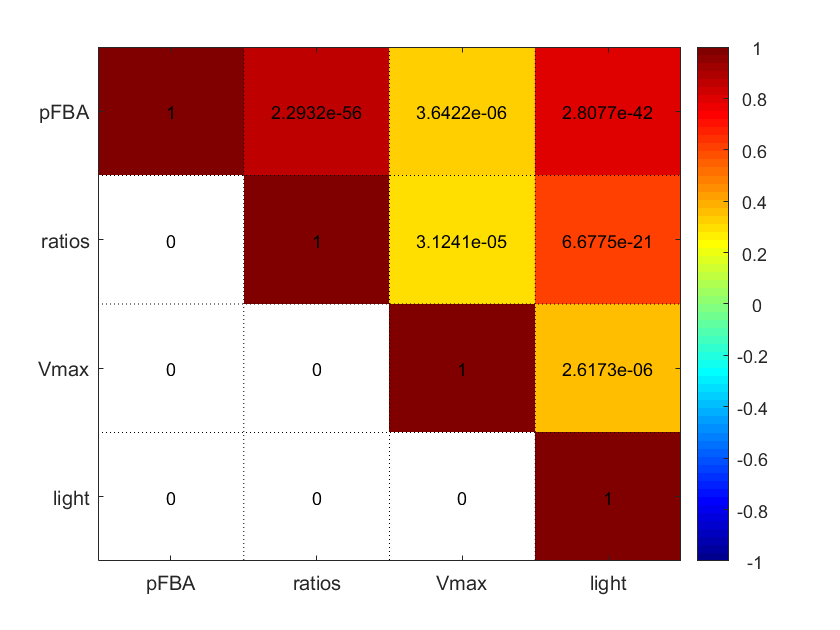

ans =   Image with properties:

           CData: [4×4×3 double]
    CDataMapping: 'direct'

  Show all properties


[C,P]=corr([kmax_vivo_pFBA kmax_vivo_ratios{best_row_ss_ratios,best_col_co_ratios} ...
    kmax_vivo_ratios_Vmax{best_row_ss_ratios_Vmax,best_col_co_ratio_Vmax} ...
    kmax_vivo_light{best_row_ss_light,best_col_co_light}],'rows','pairwise');
C_upper=triu(C);
C_upper(C_upper==0) = nan;
P_upper=triu(P);
P_upper(C_upper==0) = nan;

figure 
subplot(1,2,1)
heatmap(C_upper,{'growth', 'flux ratios', 'Vmax', 'uptake rates'},{'pFBA', 'ratios', 'Vmax', 'light'},'%0.2f','Colormap',jet,'ColorBar',0,'MinColorValue',-1,'MaxColorValue',1,'NaNColor',[1 1 1],'GridLines', ':')


[C,P]=corr([kmax_vivo_pFBA kmax_vivo_ratios{best_row_ss_ratios,best_col_co_ratios} ...
    kmax_vivo_ratios_Vmax{best_row_ss_ratios_Vmax,best_col_co_ratio_Vmax} ...
    kmax_vivo_light{best_row_ss_light,best_col_co_light}],'type','Spearman','rows','pairwise');
C_upper=triu(C);
C_upper(C_upper==0) = nan;
P_upper=triu(P);
P_upper(C_upper==0) = nan;

subplot(1,2,2)
heatmap(C_upper,{'growth', 'flux ratios', 'Vmax', 'uptake rates'},{'pFBA', 'ratios', 'Vmax', 'light'},'%0.2f','Colormap',jet,'ColorBar',0,'MinColorValue',-1,'MaxColorValue',1,'NaNColor',[1 1 1],'GridLines', ':')

id=find(all(~isnan([kmax_vivo_pFBA kmax_vivo_ratios{best_row_ss_ratios,best_col_co_ratios} ...
    kmax_vivo_ratios_Vmax{best_row_ss_ratios_Vmax,best_col_co_ratio_Vmax} ...
    kmax_vivo_light{best_row_ss_light,best_col_co_light}]')));

CV_kmax_vivo_v_estimates=std([kmax_vivo_pFBA kmax_vivo_ratios{best_row_ss_ratios,best_col_co_ratios} ...
    kmax_vivo_ratios_Vmax{best_row_ss_ratios_Vmax,best_col_co_ratio_Vmax} ...
    kmax_vivo_light{best_row_ss_light,best_col_co_light}]')./mean([kmax_vivo_pFBA kmax_vivo_ratios{best_row_ss_ratios,best_col_co_ratios} ...
    kmax_vivo_ratios_Vmax{best_row_ss_ratios_Vmax,best_col_co_ratio_Vmax} ...
    kmax_vivo_light{best_row_ss_light,best_col_co_light}]')

CV_kmax_vivo_v_estimates =        NaN         0    0.0000    0.0000    1.2875    1.0468    0.5898       NaN       NaN    1.3546       NaN       NaN    0.5913    0.0000    0.0000    1.0918    0.9578    0.2632    0.2117    0.2117    0.9057         0    0.2117    1.4455    1.2832    1.9948    0.0000    1.9636    1.5928    0.7821    1.0433       NaN    1.1960       NaN    0.0000    0.0000    0.8673    0.0000    0.9255       NaN       NaN    0.6654       NaN    0.5517    1.9517       NaN    1.0599    0.0000       NaN       NaN



mean(CV_kmax_vivo_v_estimates,'omitnan')

ans = 0.6035

median(CV_kmax_vivo_v_estimates,'omitnan')

ans = 0.4886

max(CV_kmax_vivo_v_estimates,[],'omitnan')

ans = 1.9948

sum(~isnan(CV_kmax_vivo_v_estimates))

ans = 167

# Figures

## Figure 4

% Figure 4
load("Names_of_example_enzymes.mat")
figure
subplot(1,3,1)
plot(kapp_Vmax_combined_all_max,kmax_vivo_light{best_row_ss_light,best_col_co_light},'.');
text(kapp_Vmax_combined_all_max,kmax_vivo_light{best_row_ss_light,best_col_co_light},NAMES,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',8)

xlabel('k_{cat}^{Vmax} [s^{-1}]')
ylabel('k_{max}^{vivo} [s^{-1}]')
set(gca,'XScale','Log','YScale','Log')
hold on
plot([1e-2 1e6],[1e-2 1e6],'k')
hold on
[~,m,b]=regression(log(kapp_Vmax_combined_all_max)',log(kmax_vivo_light{best_row_ss_light,best_col_co_light})');
x=log([1e-4; 1e-3; 1e-2; 1e-1;1e0; 1e1; 1e2;1e3;1e4;1e5;1e6; 1e7]);
y=(m.*x)+b;
plot(exp(x),exp(y),'-b')
xlim([1e-2 1e6])
ylim([1e-2 1e6])

subplot(1,3,2)
plot(kcat_BRENDA_mean,kmax_vivo_light{best_row_ss_light,best_col_co_light},'.');
text(kcat_BRENDA_mean,kmax_vivo_light{best_row_ss_light,best_col_co_light},NAMES,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',8)

xlabel('in vitro k_{cat} [s^{-1}]')
% ylabel('k_{app}')
set(gca,'XScale','Log','YScale','Log')
hold on
xlim([1e-2 1e6])
ylim([1e-2 1e6])
plot([1e-4 1e7],[1e-4 1e7],'k')
hold on
[~,m,b]=regression(log(kcat_BRENDA_mean)',log(kmax_vivo_light{best_row_ss_light,best_col_co_light})');
x=log([1e-4; 1e-3; 1e-2; 1e-1;1e0; 1e1; 1e2;1e3;1e4;1e5;1e6; 1e7]);
y=(m.*x)+b;
plot(exp(x),exp(y),'-b')

x=log(kmax_vivo_light{best_row_ss_light,best_col_co_light}(kcat_BRENDA_mean>0));
y=log(kcat_BRENDA_mean(kcat_BRENDA_mean>0));
NAMES_1=NAMES((kcat_BRENDA_mean>0));

subplot(1,3,3)
plot(exp(y(Comp.number(kcat_BRENDA_mean>0)==1)),exp(x(Comp.number(kcat_BRENDA_mean>0)==1)),'.');
text(exp(y(Comp.number(kcat_BRENDA_mean>0)==1)),exp(x(Comp.number(kcat_BRENDA_mean>0)==1)),NAMES_1(Comp.number(kcat_BRENDA_mean>0)==1),'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',8)

xlabel('in vitro k_{cat} [s^{-1}]')
% ylabel('k_{app}')
set(gca,'XScale','Log','YScale','Log')
hold on
xlim([1e-2 1e6])
ylim([1e-2 1e6])
plot([1e-4 1e7],[1e-4 1e7],'k')
hold on
[~,m,b]=regression(y(Comp.number(kcat_BRENDA_mean>0)==1)',x(Comp.number(kcat_BRENDA_mean>0)==1)');
xr=log([1e-4; 1e-3; 1e-2; 1e-1;1e0; 1e1; 1e2;1e3;1e4;1e5;1e6; 1e7]);
yr=(m.*xr)+b;
plot(exp(xr),exp(yr),'-b')

disp('Correlation for enzymes in single compartment:')
[C,P]=corr(x(Comp.number(kcat_BRENDA_mean>0)==1),y(Comp.number(kcat_BRENDA_mean>0)==1),'rows','pairwise')
disp('Number of enzymes:')
length(intersect(find(~isnan(x(Comp.number(kcat_BRENDA_mean>0)==1))),find(~isnan(y(Comp.number(kcat_BRENDA_mean>0)==1)))))

## Supplementary Figure 3

disp('Flux variability in flux estimates:')
figure
subplot(2,2,1)
x=max((Diff_flux_pFBA./max(model_irr.ub)),[],2,'omitnan');
[H,b]=hist(x(:),50);
bar(b,(H/sum(H)),1)
ylabel('Fraction')
title('A')

subplot(2,2,2)
x=max((Diff_flux_ratios{best_row_ss_ratios,best_col_co_ratios}./max(model_irr.ub)),[],2,'omitnan');
[H,b]=hist(x(:),50);
bar(b,(H/sum(H)),1)
title('B')

subplot(2,2,3)
x=max((Diff_flux_ratios_Vmax{best_row_ss_ratios_Vmax,best_col_co_ratio_Vmax}./max(model_irr.ub)),[],2,'omitnan');
[H,b]=hist(x(:),50);
bar(b,(H/sum(H)),1)
xlabel('Flux variability with respect to maximum flux [%]')
ylabel('Fraction')
title('C')

subplot(2,2,4)
x=max((Diff_flux_light{best_row_ss_light,best_col_co_light}./max(model_irr.ub)),[],2,'omitnan');
[H,b]=hist(x(:),50);
bar(b,(H/sum(H)),1)
%xlabel('Flux variability with respect to maximum flux [%]')
title('D')

## Supplementary Figure 4

% SUPPLEMENTARY FIGURE 4 
% k_max_vivo ~ in vitro kcat (all enzymes)
figure
subplot(2,2,1)
heatmap(C_Vmax,co_ratio,ss_ratio,[],'Colormap',jet,'ColorBar',0,'MinColorValue',-0.1,'MaxColorValue',0.7,'NaNColor',[1 1 1],'GridLines', ':')
% xlabel('carboxylation/oxygenation ratio')
ylabel('starch/sucrose synthases')
title('k_{max}^{vivo} and k_{cat}^{Vmax}')

subplot(2,2,2)
heatmap(C_all_data_mean,co_ratio,ss_ratio,[],'Colormap',jet,'ColorBar',1,'MinColorValue',-0.1,'MaxColorValue',0.7,'NaNColor',[1 1 1],'GridLines', ':')
% xlabel('carboxylation/oxygenation ratio')
% ylabel('starch/sucrose synthase ratio')
title('k_{max}^{vivo} and mean k_{cat} for enzymes with available V_{max}')

subplot(2,2,3)
heatmap(C_mean,co_ratio,ss_ratio,[],'Colormap',jet,'ColorBar',0,'MinColorValue',-0.1,'MaxColorValue',0.7,'NaNColor',[1 1 1],'GridLines', ':')
xlabel('carboxylation/oxygenation')
ylabel('starch/sucrose synthases')
title('k_{max}^{vivo} and mean k_{cat}')

subplot(2,2,4)
heatmap(C_max,co_ratio,ss_ratio,[],'Colormap',jet,'ColorBar',1,'MinColorValue',-0.1,'MaxColorValue',0.7,'NaNColor',[1 1 1],'GridLines', ':')
xlabel('carboxylation/oxygenation')
% ylabel('starch/sucrose synthase ratio')
title('k_{max}^{vivo} and maximum k_{cat}')
